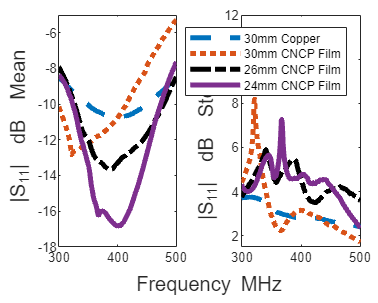

DirectoryName = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\30mm_Copper_SilverEpoxy\LogMag\";
DirectoryName2 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\30mm\LogMag\";
DirectoryName3 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\26mm\LogMag\";
DirectoryName4 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\24mm\LogMag\";

FileNames = [
    "PF T1.xlsx";
    "PF T2.xlsx";
    "PF T3.xlsx";
    "PF T4.xlsx";
    "PF T5.xlsx";
    "PF T6.xlsx";
    "PF T7.xlsx";
    "PF T8.xlsx";
    "PF T9.xlsx";
    "PF T10.xlsx";
    "PF T11.xlsx";
    "PF T12.xlsx";
    "PF T13.xlsx";
    "PF T14.xlsx";
    "PF T15.xlsx";
    "PF T16.xlsx";
    "PF T17.xlsx";
    "PF T18.xlsx";
    "PF T19.xlsx";
    "PF T20.xlsx";
    "PF T21.xlsx";
    "PF T22.xlsx";
    "PF T23.xlsx";
    "PF T24.xlsx";
    "PF T25.xlsx";
    "PF T26.xlsx";
    "PF T27.xlsx";
    "PF T28.xlsx";
    "PF T29.xlsx";
    "PF T30.xlsx";
    ];

FileNames2 = [
    "PF T1.csv";
    "PF T2.csv";
    "PF T3.csv";
    "PF T4.csv";
    "PF T5.csv";
    "PF T6.csv";
    "PF T7.csv";
    "PF T8.csv";
    "PF T9.csv";
    "PF T10.csv";
    "PF T11.csv";
    "PF T12.csv";
    "PF T13.csv";
    "PF T14.csv";
    "PF T15.csv";
    "PF T16.csv";
    "PF T17.csv";
    "PF T18.csv";
    "PF T19.csv";
    "PF T20.csv";
    "PF T21.csv";
    "PF T22.csv";
    "PF T23.csv";
    "PF T24.csv";
    "PF T25.csv";
    "PF T26.csv";
    "PF T27.csv";
    "PF T28.csv";
    "PF T29.csv";
    "PF T30.csv";
    "PF T31.csv";
    "PF T32.csv";
    "PF T33.csv";
    "PF T34.csv";
    "PF T35.csv";
    "PF T36.csv";
    "PF T37.csv";
    "PF T38.csv";
    "PF T39.csv";
    "PF T40.csv";
    "PF T41.csv";
    "PF T42.csv";
    "PF T43.csv";
    "PF T44.csv";
    "PF T45.csv";
    "PF T46.csv";
    "PF T47.csv";
    "PF T48.csv";
    "PF T49.csv";
    "PF T50.csv";
    "PF T51.csv";
    "PF T52.csv";
    "PF T53.csv";
    "PF T54.csv";
    "PF T55.csv";
    "PF T56.csv";
    "PF T57.csv";
    "PF T58.csv";
    "PF T59.csv";
    "PF T60.csv";
    "PF T61.csv";
    "PF T62.csv";
    "PF T63.csv";
    "PF T64.csv";
    "PF T65.csv";
    "PF T66.csv";
    "PF T67.csv";
    "PF T68.csv";
    "PF T69.csv";
    "PF T70.csv";
    "PF T71.csv";
    "PF T72.csv";
    "PF T73.csv";
    "PF T74.csv";
    "PF T75.csv";
    "PF T76.csv";
    "PF T77.csv";
    "PF T78.csv";
    "PF T79.csv";
    "PF T80.csv";
    "PF T81.csv";
    "PF T82.csv";
    "PF T83.csv";
    "PF T84.csv";
    "PF T85.csv";
    ];

FileCount = 1:30;
FileCount2 = 1:85;

figure('Position', [1, 1, 500, 240])
t = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
xlabel(t, sprintf('Frequency {MHz}'),'interpreter','tex', 'FontSize', 12);

%S11 Mag Mean
nexttile
[x, y, z, w, ~, ~, ~, ~, freq] = plotEpsPrimeStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount, FileNames2, FileCount2);
plot(freq, x, 'LineStyle','--', 'LineWidth', 3);
hold on;
plot(freq, y, 'LineStyle',':', 'LineWidth', 3);
hold on;
plot(freq, z, 'k', 'LineStyle','-.', 'LineWidth', 3);
hold on;
plot(freq, w, 'LineStyle','-', 'LineWidth', 3);
hold off;
ylabel(' |S_{11}| { dB } Mean', "FontSize", 12);
ylim([-18 -5]);

%S11 Standard Deviation
nexttile
[~, ~, ~, ~, x, y, z, w, freq] = plotEpsPrimeStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount, FileNames2, FileCount2);
plot(freq, x, 'LineStyle','--', 'LineWidth', 3);
hold on;
plot(freq, y, 'LineStyle',':', 'LineWidth', 3);
hold on;
plot(freq, z, 'k', 'LineStyle','-.', 'LineWidth', 3);
hold on;
plot(freq, w, 'LineStyle','-', 'LineWidth', 3);
hold off;
ylabel(' |S_{11}| { dB } Std. Dev.', "FontSize", 12);
ylim([1.5 12]);
legend('30mm Copper', '30mm CNCP Film', '26mm CNCP Film', '24mm CNCP Film', 'Location', 'northeast');

function [s11_mean, s11_mean2, s11_mean3, s11_mean4, s11_std, s11_std2, s11_std3, s11_std4, freq] = plotEpsPrimeStats(DirectoryName, DirectoryName2, DirectoryName3, DirectoryName4, FileNames, FileCount, FileNames2, FileCount2)

    % Preallocate a matrix to store the data
    % 30 measurements and 201 frequency points
s11_all = zeros(85, 201); 
s11_all2 = zeros(30, 201); 
s11_all3 = zeros(30, 201); 
s11_all4 = zeros(30, 201); 

for loopFiles = FileCount
    % Read the matrix for this file
    % VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)), 'Range', 14); %14 skips the 14 headers
    VNA_Zdata2 = readmatrix(strcat(DirectoryName2,FileNames(loopFiles,:)));
    VNA_Zdata3 = readmatrix(strcat(DirectoryName3,FileNames(loopFiles,:))); 
    VNA_Zdata4 = readmatrix(strcat(DirectoryName4,FileNames(loopFiles,:))); 

    % Store the entire frequency range's measurement
    % for the current measurement file. Adjust the columns as necessary.
    s11_all2(loopFiles, :) = VNA_Zdata2(:, 2).'; % Transpose to match the row orientation
    s11_all3(loopFiles, :) = VNA_Zdata3(:, 2).'; 
    s11_all4(loopFiles, :) = VNA_Zdata4(:, 2).'; 
end

for loopFiles2 = FileCount2
    % Read the matrix for this file
    % VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames2(loopFiles2,:)), 'Range', 8);
    VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames2(loopFiles2,:)));

    % Store the entire frequency range's measurement
    % for the current measurement file. Adjust the columns as necessary.
    s11_all(loopFiles2, :) = VNA_Zdata(:, 2).'; % Transpose to match the row orientation

end


s11_mean = mean(s11_all, 1); % 1 specifies to operate along the rows \\MEAN
s11_mean2 = mean(s11_all2, 1);
s11_mean3 = mean(s11_all3, 1);
s11_mean4 = mean(s11_all4, 1);
s11_std = std(s11_all, 0, 1); % 0 for default normalization, 1 to operate along the rows \\STD
s11_std2 = std(s11_all2, 0, 1);
s11_std3 = std(s11_all3, 0, 1);
s11_std4 = std(s11_all4, 0, 1);

freq = linspace(300, 500, 201); % Generates 201 linearly spaced points from 300 to 500

end
